I am glad you are using my code. I will be happy to receive your feedback and help you if needed. If necessary, please contact me at habib@mm.bme.hu. If you use this software for your research, please cite my paper: Habib, G. (2021). Dynamical integrity assessment of stable equilibria: a new rapid iterative procedure. Nonlinear Dynamics, 106(3), 2073-2096

clear
% close all
% clc

Parameter values for the system and for the computation


% parameter values
zeta=0.05;
b=1;
a=1;
par=[zeta b a];
% the equation of motion is x''+2*zeta*x'-a*x+b*x^3=0

% wieght for computing the distance in the phase space. The first term
% correspond to the natural frequency squared. For more information look at
% Habib, G. (2021). Dynamical integrity assessment of stable equilibria: a 
% new rapid iterative procedure. Nonlinear Dynamics, 106(3), 2073-2096.
weight=[4 1];

% equilibrium point
xe=[-1,0];

% variable of the phase space to be plot (unnecessary for this system,
% since it has only 1 DoF)
var1=1;
var2=2;

% number of step of the iteration
number_of_steps=50;

% space boundary
spaceboundary=[xe-2,xe+4];

% discretization of the phase space in each direction
discr=701;

Computation of the Local Integrity Measure (LIM) of the system using different methods for initial condition selection

The first one, initial condition selection as the farthest unexplorated point in the hypersphere of convergence (type_x0=1) is the slowest, since it needs additional time to select the initial condition. Conversely, it aims at exploring uniformly the phase space, which increases the probability that no steady state solution is overlooked.

The second one, initial condition selection through the bisection method, aims at finding trajectories on the boundary of he basin of attraction. It is rapid and in many cases the most accurate. However, the probability that other steady state solutions are overlooked is not negligible.

The third one uses a fully random algorithm for initial condition selection. It is rapid as the second one, and covers rather uniformely the phase space within the hypersphere of convergence.

We don't claim that any method is better than the other ones. They all have their pros and cons.

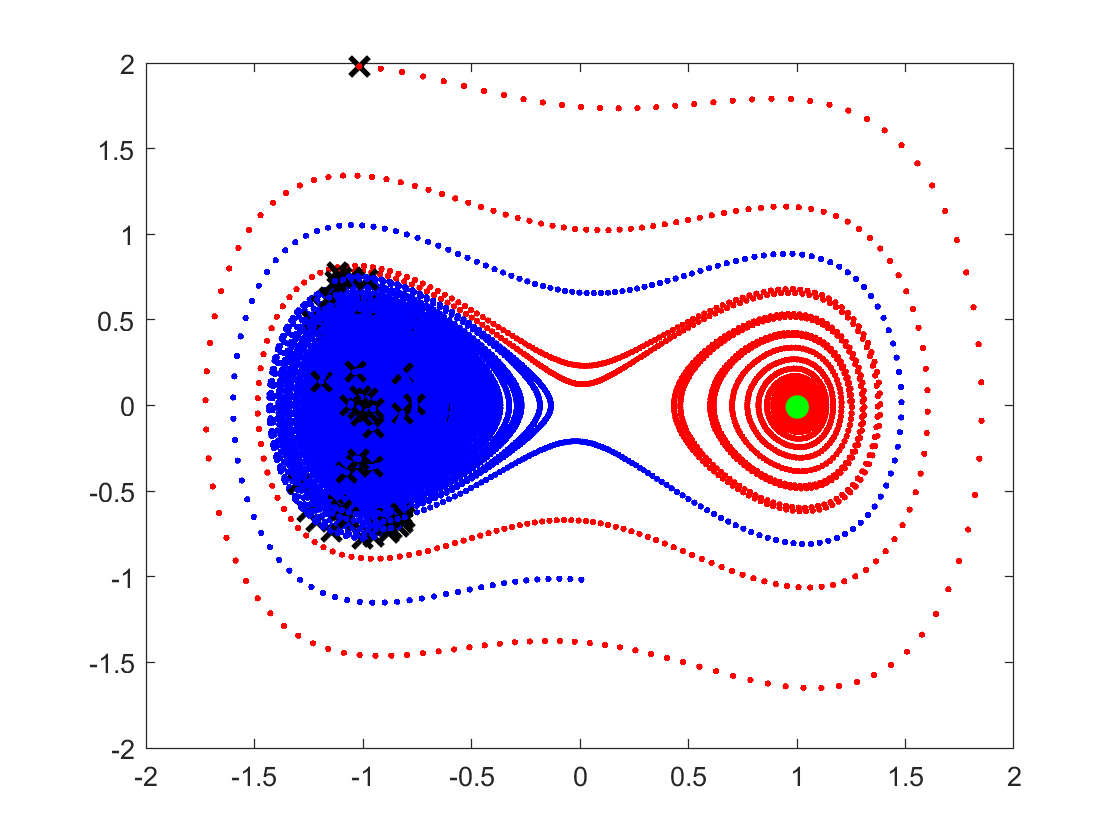

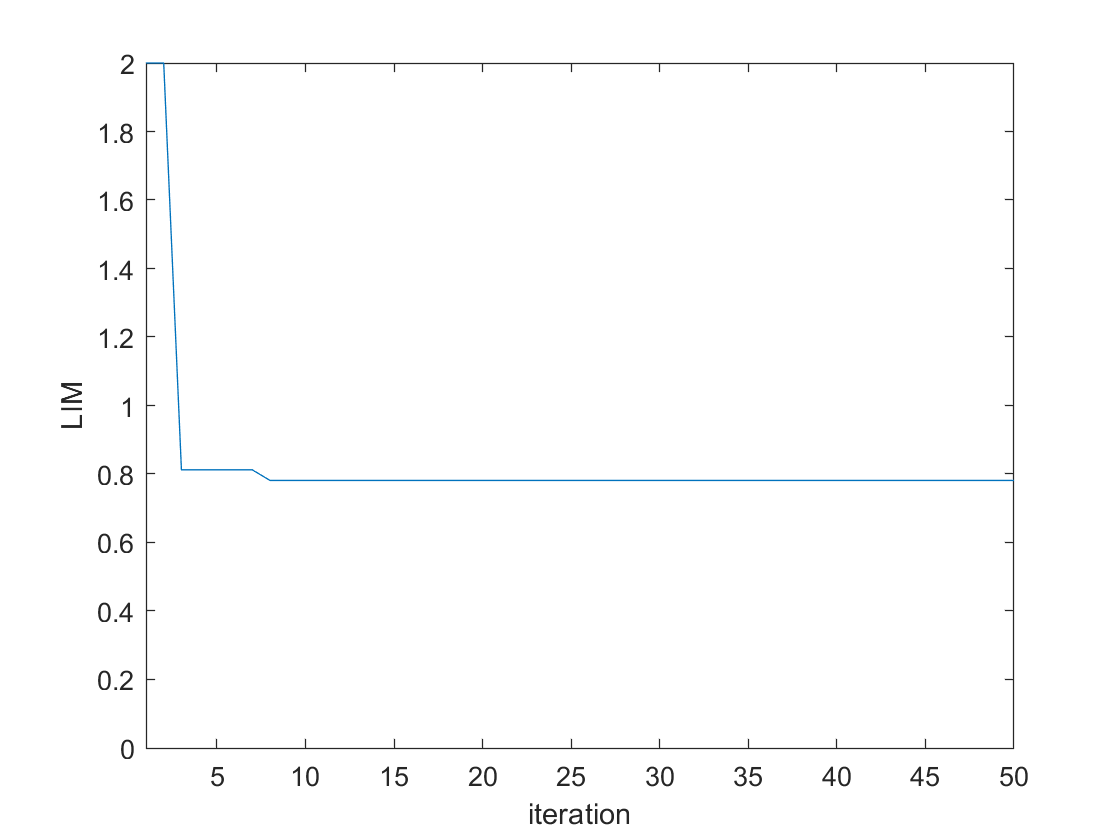

% computation of the LIM. Initial conditions selected as the farthest
% unexplorated point in the hypersphere of convergence (type_x0=1)

[LIM,R,time_sim,time_x0,time_steps,time_steps_sim,total_time,distance,vc,vd,vdout,tipo,other_solutions_p,num_points_inside,x0]=...
    compute_LIM_FP(xe,par,'weight',weight,'plot_results',1,'plot_results_final',0,'number_of_steps',number_of_steps,...
    'spaceboundary',spaceboundary,'discr',discr,'tfinal',2000,'num_of_cell_around_equilibrium',3,'divR',50,'num_gen',5,...
    'type_x0',1,'var1',var1,'var2',var2);

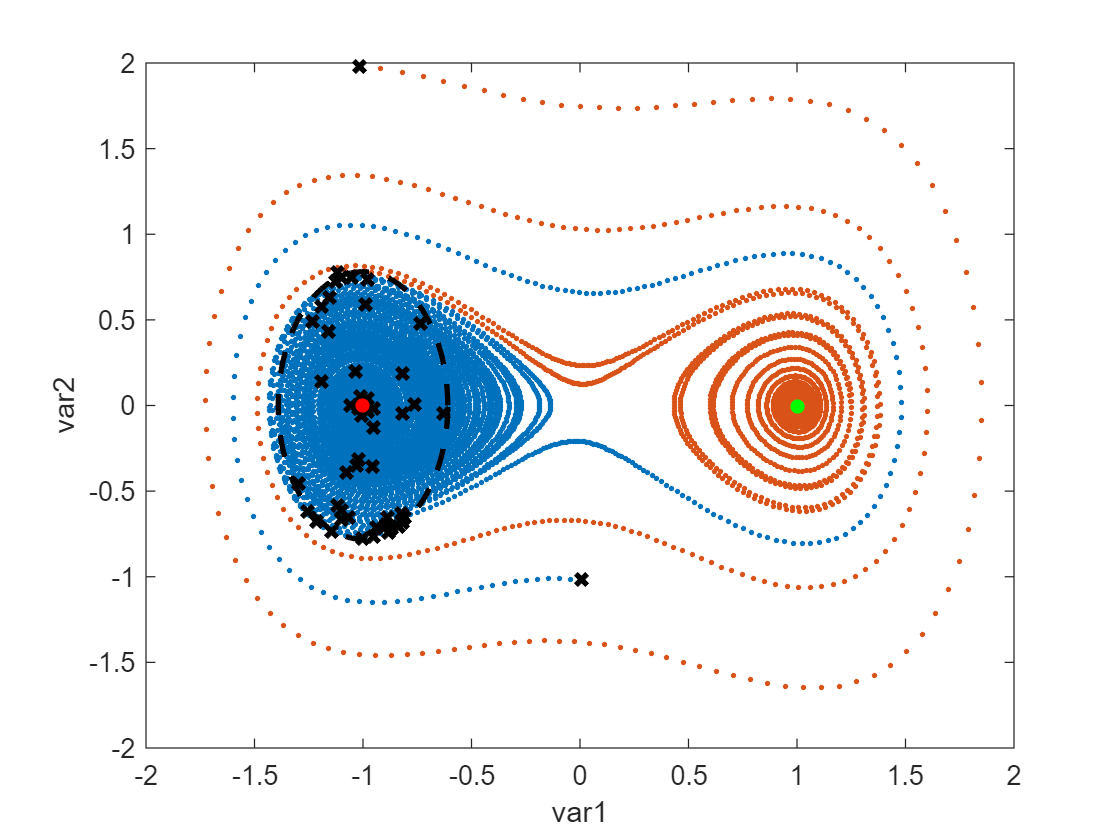


% plot the phase space with all trajectories, initial conditions 
% utilized and new steady state solutions identified
figure;plot(vc(:,var1),vc(:,var2),'.',vd(:,var1),vd(:,var2),'.',vdout(:,var1),vdout(:,var2),'.',x0(:,var1),x0(:,var2),'kx',...
    'LineWidth',2);xlabel('var1');ylabel('var2');hold on;
for i=1:length(other_solutions_p)
    plot(other_solutions_p{i,1}(:,var1),other_solutions_p{i,1}(:,var2),'g.','MarkerSize',16);
end
plot(xe(:,var1),xe(:,var2),'r.','MarkerSize',16);

% plot a circle representing the LIM
phi=linspace(0,2*pi,1000);
Rw=LIM;
dim=length(xe);
xcircW=zeros(length(phi),2);
if exist('var1','var')==0
    var1=1;
end
if exist('var2','var')==0
    var2=2;
end
for i=1:length(phi)
    for i2=1:2:dim
        xcircW(i,:)=[xe(var1)+Rw/sqrt(weight(var1))*cos(phi(i)),xe(var2)+Rw/sqrt(weight(var2))*sin(phi(i))];
    end
end
plot(xcircW(:,1),xcircW(:,2),'k--','LineWidth',2);


disp('Estimated LIM, initial condition selection as the farthest point in hypersphere of convergence')

Estimated LIM, initial condition selection as the farthest point in hypersphere of convergence


LIM

LIM = 0.7812

% computation of the LIM. Initial conditions selected through a bisection
% algorithm for finding trajectories on the boundary of the basin of
% attraction (type_x0=2)

[LIM,R,time_sim,time_x0,time_steps,time_steps_sim,total_time,distance,vc,vd,vdout,tipo,other_solutions_p,num_points_inside,x0]=...
    compute_LIM_FP(xe,par,'weight',weight,'plot_results',1,'plot_results_final',0,'number_of_steps',number_of_steps,...
    'spaceboundary',spaceboundary,'discr',discr,'tfinal',2000,'num_of_cell_around_equilibrium',3,...
    'type_x0',2,'bis_iter_max',5,'var1',var1,'var2',var2);

% plot the phase space with all trajectories, initial conditions 
% utilized and new steady state solutions identified
figure;plot(vc(:,var1),vc(:,var2),'.',vd(:,var1),vd(:,var2),'.',vdout(:,var1),vdout(:,var2),'.',x0(:,var1),x0(:,var2),'kx',...
    'LineWidth',2);xlabel('var1');ylabel('var2');hold on;
for i=1:length(other_solutions_p)
    plot(other_solutions_p{i,1}(:,var1),other_solutions_p{i,1}(:,var2),'g.','MarkerSize',16);
end
plot(xe(:,var1),xe(:,var2),'r.','MarkerSize',16);

% plot a circle representing the LIM
phi=linspace(0,2*pi,1000);
Rw=LIM;
dim=length(xe);
xcircW=zeros(length(phi),2);
if exist('var1','var')==0
    var1=1;
end
if exist('var2','var')==0
    var2=2;
end
for i=1:length(phi)
    for i2=1:2:dim
        xcircW(i,:)=[xe(var1)+Rw/sqrt(weight(var1))*cos(phi(i)),xe(var2)+Rw/sqrt(weight(var2))*sin(phi(i))];
    end
end
plot(xcircW(:,1),xcircW(:,2),'k--','LineWidth',2);

disp('LIM estimated through bisection method for initial condition selection')
LIM

% computation of the LIM using random initial conditions (type_x0=3)

[LIM,R,time_sim,time_x0,time_steps,time_steps_sim,total_time,distance,vc,vd,vdout,tipo,other_solutions_p,num_points_inside,x0]=...
    compute_LIM_FP(xe,par,'weight',weight,'plot_results',1,'plot_results_final',0,'number_of_steps',number_of_steps,...
    'spaceboundary',spaceboundary,'discr',discr,'tfinal',2000,'num_of_cell_around_equilibrium',3,...
    'type_x0',3,'var1',var1,'var2',var2);

% plot the phase space with all trajectories, initial conditions 
% utilized and new steady state solutions identified
figure;plot(vc(:,var1),vc(:,var2),'.',vd(:,var1),vd(:,var2),'.',vdout(:,var1),vdout(:,var2),'.',x0(:,var1),x0(:,var2),'kx',...
    'LineWidth',2);xlabel('var1');ylabel('var2');hold on;
for i=1:length(other_solutions_p)
    plot(other_solutions_p{i,1}(:,var1),other_solutions_p{i,1}(:,var2),'g.','MarkerSize',16);
end
plot(xe(:,var1),xe(:,var2),'r.','MarkerSize',16);

% plot a circle representing the LIM
phi=linspace(0,2*pi,1000);
Rw=LIM;
dim=length(xe);
xcircW=zeros(length(phi),2);
if exist('var1','var')==0
    var1=1;
end
if exist('var2','var')==0
    var2=2;
end
for i=1:length(phi)
    for i2=1:2:dim
        xcircW(i,:)=[xe(var1)+Rw/sqrt(weight(var1))*cos(phi(i)),xe(var2)+Rw/sqrt(weight(var2))*sin(phi(i))];
    end
end
plot(xcircW(:,1),xcircW(:,2),'k--','LineWidth',2);

disp('LIM estimated through random initial condition selection')
LIM






% parametric analysis. Analysis of LIM for variation of the cubic
% stiffness. In this part of the code, the LIM value is computed for
% different cubic stiffness values of the Duffing oscillator b. For each b
% value the equilibrium position must be specified.

% varying system parameter (the other parameters are those provided above)
a=linspace(0.05,2,20);

% computational parameters
number_of_steps=40;
discr=701;

% initialization of LIM
LIM=zeros(length(a),1);

% computation
parfor i=1:length(a)
    par=[zeta b a(i)]; % parameters change at each iteration
    xe=[-sqrt(b/a(i)), 0]; % equilibrium changes at each iteration
    spaceboundary=[xe-5,xe+5]; % % boundaries must change depending on equilibrium
[LIM(i)]=...
    compute_LIM_FP(xe,par,'weight',weight,'plot_results',0,'plot_results_final',0,'number_of_steps',number_of_steps,...
    'spaceboundary',spaceboundary,'discr',discr,'tfinal',2000,'num_of_cell_around_equilibrium',3,...
    'type_x0',2,'bis_iter_max',5,'var1',var1,'var2',var2);
end

% visualization of the results
figure;plot(a,LIM,'LineWidth',2);xlabel('a');ylabel('LIM');




